%%INPUTS

%Flight Conditions
h = 0 %ft

h = 0

V = 100; %kts
[TempRat, PresRat, DensRat, SpeedSound] = ISA(h);
AirDens = DensRat*2.3769*10^-3

AirDens = 0.0024

V=V*1.688

V = 168.8000

AoA = 0;

%Wing Parameters
QuarterSweep = 0 %deg

QuarterSweep = 0

Df = 15.5;
TaperRatio = 0.4

TaperRatio = 0.4000

S = 1693

S = 1693

b = 118

b = 118

AR = b^2/S

AR = 8.2245

SweepLE = atand(tand(QuarterSweep)-4/AR*((0-0.25)*(1-TaperRatio)/(1+TaperRatio)))

SweepLE = 2.9830

InstallAngle = 2.73

InstallAngle = 2.7300

LiftCurveSlope = 0.0863 %Per deg

LiftCurveSlope = 0.0863


%Prop Parameters
ThrustAngle = 0

ThrustAngle = 0

Rp = 10

Rp = 10

%HP = 18698*2 %Per engine
PropEff = 0.81

PropEff = 0.8100

zProp = 4

zProp = 4


%Thrust = HP*0.81/V*550
Thrust = 12000*2

Thrust = 24000


x1 = 20.5

x1 = 20.5000

x2 = 42.5

x2 = 42.5000


ThrustCoef = Thrust/(0.5*AirDens*V^2*S) 

ThrustCoef = 0.4186

PropCorrelationParam = S*ThrustCoef/(8*Rp^2) %Use to find f

PropCorrelationParam = 0.8859

Sp = pi*Rp^2

Sp = 314.1593


%DATCOM Figures
PropNormForceCoeff = 0.5 %Pg 1387 Depends on Nominal Blade Anlgle and # of props

PropNormForceCoeff = 0.5000

PropUpwashGradient = 0.4 %Pg 1275 Depends on AR and Prop Distance from 0.25Cr

PropUpwashGradient = 0.4000

f = 1.5 %Pg 1387 Depends on PropCorrelationParam

f = 1.5000

C1 = 0.3 %Pg 1388 Depends on PropCorrelationParam

C1 = 0.3000

C2 = 0.2 %Pg 1388 Depends on PropCorrelationParam

C2 = 0.2000

K = 1 %Pg 1398 Depends on Si/S

K = 1

K1 = 0.8 %Pg 1389 Depends on Prop CorrelationParam, AR, AR immersed

K1 = 0.8000

K2 = 0.8 %Pg 1389 Depends on Prop CorrelationParam, AR, AR immersed

K2 = 0.8000


%For clean wing
daCLmax = 1.2

daCLmax = 1.2000

MaxLiftCoefRatio = 0.9

MaxLiftCoefRatio = 0.9000


%Airfoil Parameters
ZeroLiftAngle = -3

ZeroLiftAngle = -3

ClMax = 1.6

ClMax = 1.6000

AirfoilStallAngle = 16

AirfoilStallAngle = 16

Cla = 0.11

Cla = 0.1100



%Clean wing
CLMax = MaxLiftCoefRatio*ClMax

CLMax = 1.4400

WingStallAngle = CLMax/LiftCurveSlope+ZeroLiftAngle+daCLmax

WingStallAngle = 14.8860


%Flapped From Graphs
FlapDeflec = 40 %Deg

FlapDeflec = 40

ddZeroLiftAngle = -0.45 %For Slotted flaps with cf/c = 0.3 at 40deg deflection

ddZeroLiftAngle = -0.4500

dZeroLiftAngle = ddZeroLiftAngle*FlapDeflec

dZeroLiftAngle = -18


%%CALCULATIONS

%Flapped Wing
y1flap=Df/2

y1flap = 7.7500

y2flap=0.75*b/2

y2flap = 44.2500

y3flap=0

y3flap = 0

y4flap=0

y4flap = 0


y3Aileron = 56.05

y3Aileron = 56.0500


cr = 2*S/(b*(1+TaperRatio))

cr = 20.4964


c1flap = cr*(1-(1-TaperRatio)*2*y1flap/b)

c1flap = 18.8810

c2flap = cr*(1-(1-TaperRatio)*2*y2flap/b)

c2flap = 11.2730

c3flap = cr*(1-(1-TaperRatio)*2*y3flap/b)

c3flap = 20.4964

c4flap = cr*(1-(1-TaperRatio)*2*y4flap/b)

c4flap = 20.4964


c3Aileron = cr*(1-(1-TaperRatio)*2*y3Aileron/b)

c3Aileron = 8.8134


SWF = 2*((c1flap+c2flap)/2*(y2flap-y1flap) + (c3flap+c4flap)/2*(y4flap-y3flap))

SWF = 1.1006e+03

SweepFactor = (1-0.08*(cosd(QuarterSweep))^2)*(cosd(QuarterSweep))^(3/4)

SweepFactor = 0.9200


dAirfoilStallAngle = -4*10^(-7)*FlapDeflec^4+3*10^(-5)*FlapDeflec^3-0.0019*FlapDeflec^2-0.024*FlapDeflec

dAirfoilStallAngle = -3.1040


AirfoilStallAngleFlapped = AirfoilStallAngle + dAirfoilStallAngle

AirfoilStallAngleFlapped = 12.8960


ZeroLiftAngleFlapped = ZeroLiftAngle + dZeroLiftAngle

ZeroLiftAngleFlapped = -21


ClMaxFlapped = Cla*(AirfoilStallAngleFlapped - ZeroLiftAngleFlapped-daCLmax)

ClMaxFlapped = 3.5966


dClMaxFlapped = ClMaxFlapped - ClMax

dClMaxFlapped = 1.9966

dCLMaxFlapped = dClMaxFlapped*SWF*SweepFactor/S

dCLMaxFlapped = 1.1941


CLMaxFlapped = CLMax + dCLMaxFlapped

CLMaxFlapped = 2.6341


%Powered CLmax



%KN =
KN = 80.7 %ASSUMED

KN = 80.7000


TruePropNormalForceCoeff = PropNormForceCoeff*(1+0.8*(KN/80.7-1))

TruePropNormalForceCoeff = 0.5000


PropPlaneAngle = ThrustAngle + PropUpwashGradient*(AoA+InstallAngle-ZeroLiftAngle)  

PropPlaneAngle = 2.2920


dCLPropNorm = f*TruePropNormalForceCoeff*PropPlaneAngle/57.3*Sp/S*cosd(ThrustAngle)

dCLPropNorm = 0.0056


UpwashGradient = C1 + C2*TruePropNormalForceCoeff

UpwashGradient = 0.4000


PropDownwashAngle = UpwashGradient*PropPlaneAngle

PropDownwashAngle = 0.9168


dWingAoA = -PropDownwashAngle/(1+PropUpwashGradient)

dWingAoA = -0.6549


PropUpwashAngle = PropUpwashGradient*(AoA+InstallAngle-ZeroLiftAngle)

PropUpwashAngle = 2.2920


for x=1:1:27
   
    CL = (x-1)/10
    
    %Inboard Props
    y1 = 19 %ft to centerline of prop
    z1 = x1*tand(ThrustAngle+PropUpwashAngle-PropDownwashAngle)+zProp %Assuming Prop is in line with MAC on wing
    b1 = 2*sqrt(Rp^2-z1^2)
    c1 = cr*(1-(1-TaperRatio)*2*y1/b)
    S1 = b1*c1
    AReff1 = b1/c1
    dSlipstreamDynPressure1 = S*ThrustCoef/(pi*Rp^2)
    dCLWash1 = (1+dSlipstreamDynPressure1)*S1/S*LiftCurveSlope*dWingAoA*K1
    dCLq1 = K1*dSlipstreamDynPressure1*S1/S*CL
    
    %Outboard Props
    y2 = 45.5 %ft to centerline of prop
    z2 = x2*tand(ThrustAngle+PropUpwashAngle-PropDownwashAngle)+zProp %Assuming Prop is in line with MAC on wing
    b2 = 2*sqrt(Rp^2-z2^2)
    c2 = cr*(1-(1-TaperRatio)*2*y2/b)
    S2 = b2*c2
    AReff2 = b2/c2
    dSlipstreamDynPressure2 = S*ThrustCoef/(pi*Rp^2)
    dCLWash2 = (1+dSlipstreamDynPressure2)*S2/S*LiftCurveSlope*dWingAoA*K1
    dCLq2 = K2*dSlipstreamDynPressure2*S2/S*CL
    
    ImmersedRatio = (2*S1+2*S2)/S
    
    CLPowered(x) = CL + K*(4*dCLPropNorm + 2*dCLWash1 + 2*dCLq1 + 2*dCLWash2 + 2*dCLq2)

    alpha(x) = (CL/LiftCurveSlope)+ZeroLiftAngleFlapped
    
end

CL = 0

y1 = 19

z1 = 4.4921

b1 = 17.8685

c1 = 16.5361

S1 = 295.4743

AReff1 = 1.0806

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0257

dCLq1 = 0

y2 = 45.5000

z2 = 5.0203

b2 = 17.2970

c2 = 11.0125

S2 = 190.4829

AReff2 = 1.5707

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0166

dCLq2 = 0

ImmersedRatio = 0.5741

CLPowered =    -0.0622    0.1414    0.3450    0.5486    0.7522    0.9558    1.1594    1.3630    1.5666    1.7702    1.9738    2.1775    2.3811    2.5847    2.7883    2.9919    3.1955    3.3991    3.6027    3.8063    4.0099    4.2135    4.4172    4.6208    4.8244    5.0280    5.2316


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950   -5.9363   -4.7775   -3.6188   -2.4600   -1.3013   -0.1425    1.0162    2.1750    3.3337    4.4925    5.6512    6.8100    7.9687    9.1275


CL = 0.1000

y1 = 19

z1 = 4.4921

b1 = 17.8685

c1 = 16.5361

S1 = 295.4743

AReff1 = 1.0806

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0257

dCLq1 = 0.0315

y2 = 45.5000

z2 = 5.0203

b2 = 17.2970

c2 = 11.0125

S2 = 190.4829

AReff2 = 1.5707

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0166

dCLq2 = 0.0203

ImmersedRatio = 0.5741

CLPowered =    -0.0622    0.1414    0.3450    0.5486    0.7522    0.9558    1.1594    1.3630    1.5666    1.7702    1.9738    2.1775    2.3811    2.5847    2.7883    2.9919    3.1955    3.3991    3.6027    3.8063    4.0099    4.2135    4.4172    4.6208    4.8244    5.0280    5.2316


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950   -5.9363   -4.7775   -3.6188   -2.4600   -1.3013   -0.1425    1.0162    2.1750    3.3337    4.4925    5.6512    6.8100    7.9687    9.1275


CL = 0.2000

y1 = 19

z1 = 4.4921

b1 = 17.8685

c1 = 16.5361

S1 = 295.4743

AReff1 = 1.0806

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0257

dCLq1 = 0.0630

y2 = 45.5000

z2 = 5.0203

b2 = 17.2970

c2 = 11.0125

S2 = 190.4829

AReff2 = 1.5707

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0166

dCLq2 = 0.0406

ImmersedRatio = 0.5741

CLPowered =    -0.0622    0.1414    0.3450    0.5486    0.7522    0.9558    1.1594    1.3630    1.5666    1.7702    1.9738    2.1775    2.3811    2.5847    2.7883    2.9919    3.1955    3.3991    3.6027    3.8063    4.0099    4.2135    4.4172    4.6208    4.8244    5.0280    5.2316


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950   -5.9363   -4.7775   -3.6188   -2.4600   -1.3013   -0.1425    1.0162    2.1750    3.3337    4.4925    5.6512    6.8100    7.9687    9.1275


CL = 0.3000

y1 = 19

z1 = 4.4921

b1 = 17.8685

c1 = 16.5361

S1 = 295.4743

AReff1 = 1.0806

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0257

dCLq1 = 0.0945

y2 = 45.5000

z2 = 5.0203

b2 = 17.2970

c2 = 11.0125

S2 = 190.4829

AReff2 = 1.5707

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0166

dCLq2 = 0.0609

ImmersedRatio = 0.5741

CLPowered =    -0.0622    0.1414    0.3450    0.5486    0.7522    0.9558    1.1594    1.3630    1.5666    1.7702    1.9738    2.1775    2.3811    2.5847    2.7883    2.9919    3.1955    3.3991    3.6027    3.8063    4.0099    4.2135    4.4172    4.6208    4.8244    5.0280    5.2316


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950   -5.9363   -4.7775   -3.6188   -2.4600   -1.3013   -0.1425    1.0162    2.1750    3.3337    4.4925    5.6512    6.8100    7.9687    9.1275


CL = 0.4000

y1 = 19

z1 = 4.4921

b1 = 17.8685

c1 = 16.5361

S1 = 295.4743

AReff1 = 1.0806

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0257

dCLq1 = 0.1260

y2 = 45.5000

z2 = 5.0203

b2 = 17.2970

c2 = 11.0125

S2 = 190.4829

AReff2 = 1.5707

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0166

dCLq2 = 0.0812

ImmersedRatio = 0.5741

CLPowered =    -0.0622    0.1414    0.3450    0.5486    0.7522    0.9558    1.1594    1.3630    1.5666    1.7702    1.9738    2.1775    2.3811    2.5847    2.7883    2.9919    3.1955    3.3991    3.6027    3.8063    4.0099    4.2135    4.4172    4.6208    4.8244    5.0280    5.2316


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950   -5.9363   -4.7775   -3.6188   -2.4600   -1.3013   -0.1425    1.0162    2.1750    3.3337    4.4925    5.6512    6.8100    7.9687    9.1275


CL = 0.5000

y1 = 19

z1 = 4.4921

b1 = 17.8685

c1 = 16.5361

S1 = 295.4743

AReff1 = 1.0806

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0257

dCLq1 = 0.1575

y2 = 45.5000

z2 = 5.0203

b2 = 17.2970

c2 = 11.0125

S2 = 190.4829

AReff2 = 1.5707

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0166

dCLq2 = 0.1015

ImmersedRatio = 0.5741

CLPowered =    -0.0622    0.1414    0.3450    0.5486    0.7522    0.9558    1.1594    1.3630    1.5666    1.7702    1.9738    2.1775    2.3811    2.5847    2.7883    2.9919    3.1955    3.3991    3.6027    3.8063    4.0099    4.2135    4.4172    4.6208    4.8244    5.0280    5.2316


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950   -5.9363   -4.7775   -3.6188   -2.4600   -1.3013   -0.1425    1.0162    2.1750    3.3337    4.4925    5.6512    6.8100    7.9687    9.1275


CL = 0.6000

y1 = 19

z1 = 4.4921

b1 = 17.8685

c1 = 16.5361

S1 = 295.4743

AReff1 = 1.0806

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0257

dCLq1 = 0.1890

y2 = 45.5000

z2 = 5.0203

b2 = 17.2970

c2 = 11.0125

S2 = 190.4829

AReff2 = 1.5707

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0166

dCLq2 = 0.1218

ImmersedRatio = 0.5741

CLPowered =    -0.0622    0.1414    0.3450    0.5486    0.7522    0.9558    1.1594    1.3630    1.5666    1.7702    1.9738    2.1775    2.3811    2.5847    2.7883    2.9919    3.1955    3.3991    3.6027    3.8063    4.0099    4.2135    4.4172    4.6208    4.8244    5.0280    5.2316


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950   -5.9363   -4.7775   -3.6188   -2.4600   -1.3013   -0.1425    1.0162    2.1750    3.3337    4.4925    5.6512    6.8100    7.9687    9.1275


CL = 0.7000

y1 = 19

z1 = 4.4921

b1 = 17.8685

c1 = 16.5361

S1 = 295.4743

AReff1 = 1.0806

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0257

dCLq1 = 0.2205

y2 = 45.5000

z2 = 5.0203

b2 = 17.2970

c2 = 11.0125

S2 = 190.4829

AReff2 = 1.5707

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0166

dCLq2 = 0.1421

ImmersedRatio = 0.5741

CLPowered =    -0.0622    0.1414    0.3450    0.5486    0.7522    0.9558    1.1594    1.3630    1.5666    1.7702    1.9738    2.1775    2.3811    2.5847    2.7883    2.9919    3.1955    3.3991    3.6027    3.8063    4.0099    4.2135    4.4172    4.6208    4.8244    5.0280    5.2316


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950   -5.9363   -4.7775   -3.6188   -2.4600   -1.3013   -0.1425    1.0162    2.1750    3.3337    4.4925    5.6512    6.8100    7.9687    9.1275


CL = 0.8000

y1 = 19

z1 = 4.4921

b1 = 17.8685

c1 = 16.5361

S1 = 295.4743

AReff1 = 1.0806

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0257

dCLq1 = 0.2520

y2 = 45.5000

z2 = 5.0203

b2 = 17.2970

c2 = 11.0125

S2 = 190.4829

AReff2 = 1.5707

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0166

dCLq2 = 0.1624

ImmersedRatio = 0.5741

CLPowered =    -0.0622    0.1414    0.3450    0.5486    0.7522    0.9558    1.1594    1.3630    1.5666    1.7702    1.9738    2.1775    2.3811    2.5847    2.7883    2.9919    3.1955    3.3991    3.6027    3.8063    4.0099    4.2135    4.4172    4.6208    4.8244    5.0280    5.2316


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950   -5.9363   -4.7775   -3.6188   -2.4600   -1.3013   -0.1425    1.0162    2.1750    3.3337    4.4925    5.6512    6.8100    7.9687    9.1275


CL = 0.9000

y1 = 19

z1 = 4.4921

b1 = 17.8685

c1 = 16.5361

S1 = 295.4743

AReff1 = 1.0806

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0257

dCLq1 = 0.2835

y2 = 45.5000

z2 = 5.0203

b2 = 17.2970

c2 = 11.0125

S2 = 190.4829

AReff2 = 1.5707

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0166

dCLq2 = 0.1828

ImmersedRatio = 0.5741

CLPowered =    -0.0622    0.1414    0.3450    0.5486    0.7522    0.9558    1.1594    1.3630    1.5666    1.7702    1.9738    2.1775    2.3811    2.5847    2.7883    2.9919    3.1955    3.3991    3.6027    3.8063    4.0099    4.2135    4.4172    4.6208    4.8244    5.0280    5.2316


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950   -5.9363   -4.7775   -3.6188   -2.4600   -1.3013   -0.1425    1.0162    2.1750    3.3337    4.4925    5.6512    6.8100    7.9687    9.1275


CL = 1

y1 = 19

z1 = 4.4921

b1 = 17.8685

c1 = 16.5361

S1 = 295.4743

AReff1 = 1.0806

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0257

dCLq1 = 0.3150

y2 = 45.5000

z2 = 5.0203

b2 = 17.2970

c2 = 11.0125

S2 = 190.4829

AReff2 = 1.5707

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0166

dCLq2 = 0.2031

ImmersedRatio = 0.5741

CLPowered =    -0.0622    0.1414    0.3450    0.5486    0.7522    0.9558    1.1594    1.3630    1.5666    1.7702    1.9738    2.1775    2.3811    2.5847    2.7883    2.9919    3.1955    3.3991    3.6027    3.8063    4.0099    4.2135    4.4172    4.6208    4.8244    5.0280    5.2316


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950   -5.9363   -4.7775   -3.6188   -2.4600   -1.3013   -0.1425    1.0162    2.1750    3.3337    4.4925    5.6512    6.8100    7.9687    9.1275


CL = 1.1000

y1 = 19

z1 = 4.4921

b1 = 17.8685

c1 = 16.5361

S1 = 295.4743

AReff1 = 1.0806

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0257

dCLq1 = 0.3465

y2 = 45.5000

z2 = 5.0203

b2 = 17.2970

c2 = 11.0125

S2 = 190.4829

AReff2 = 1.5707

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0166

dCLq2 = 0.2234

ImmersedRatio = 0.5741

CLPowered =    -0.0622    0.1414    0.3450    0.5486    0.7522    0.9558    1.1594    1.3630    1.5666    1.7702    1.9738    2.1775    2.3811    2.5847    2.7883    2.9919    3.1955    3.3991    3.6027    3.8063    4.0099    4.2135    4.4172    4.6208    4.8244    5.0280    5.2316


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950   -5.9363   -4.7775   -3.6188   -2.4600   -1.3013   -0.1425    1.0162    2.1750    3.3337    4.4925    5.6512    6.8100    7.9687    9.1275


CL = 1.2000

y1 = 19

z1 = 4.4921

b1 = 17.8685

c1 = 16.5361

S1 = 295.4743

AReff1 = 1.0806

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0257

dCLq1 = 0.3780

y2 = 45.5000

z2 = 5.0203

b2 = 17.2970

c2 = 11.0125

S2 = 190.4829

AReff2 = 1.5707

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0166

dCLq2 = 0.2437

ImmersedRatio = 0.5741

CLPowered =    -0.0622    0.1414    0.3450    0.5486    0.7522    0.9558    1.1594    1.3630    1.5666    1.7702    1.9738    2.1775    2.3811    2.5847    2.7883    2.9919    3.1955    3.3991    3.6027    3.8063    4.0099    4.2135    4.4172    4.6208    4.8244    5.0280    5.2316


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950   -5.9363   -4.7775   -3.6188   -2.4600   -1.3013   -0.1425    1.0162    2.1750    3.3337    4.4925    5.6512    6.8100    7.9687    9.1275


CL = 1.3000

y1 = 19

z1 = 4.4921

b1 = 17.8685

c1 = 16.5361

S1 = 295.4743

AReff1 = 1.0806

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0257

dCLq1 = 0.4095

y2 = 45.5000

z2 = 5.0203

b2 = 17.2970

c2 = 11.0125

S2 = 190.4829

AReff2 = 1.5707

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0166

dCLq2 = 0.2640

ImmersedRatio = 0.5741

CLPowered =    -0.0622    0.1414    0.3450    0.5486    0.7522    0.9558    1.1594    1.3630    1.5666    1.7702    1.9738    2.1775    2.3811    2.5847    2.7883    2.9919    3.1955    3.3991    3.6027    3.8063    4.0099    4.2135    4.4172    4.6208    4.8244    5.0280    5.2316


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950   -5.9363   -4.7775   -3.6188   -2.4600   -1.3013   -0.1425    1.0162    2.1750    3.3337    4.4925    5.6512    6.8100    7.9687    9.1275


CL = 1.4000

y1 = 19

z1 = 4.4921

b1 = 17.8685

c1 = 16.5361

S1 = 295.4743

AReff1 = 1.0806

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0257

dCLq1 = 0.4410

y2 = 45.5000

z2 = 5.0203

b2 = 17.2970

c2 = 11.0125

S2 = 190.4829

AReff2 = 1.5707

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0166

dCLq2 = 0.2843

ImmersedRatio = 0.5741

CLPowered =    -0.0622    0.1414    0.3450    0.5486    0.7522    0.9558    1.1594    1.3630    1.5666    1.7702    1.9738    2.1775    2.3811    2.5847    2.7883    2.9919    3.1955    3.3991    3.6027    3.8063    4.0099    4.2135    4.4172    4.6208    4.8244    5.0280    5.2316


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950   -5.9363   -4.7775   -3.6188   -2.4600   -1.3013   -0.1425    1.0162    2.1750    3.3337    4.4925    5.6512    6.8100    7.9687    9.1275


CL = 1.5000

y1 = 19

z1 = 4.4921

b1 = 17.8685

c1 = 16.5361

S1 = 295.4743

AReff1 = 1.0806

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0257

dCLq1 = 0.4725

y2 = 45.5000

z2 = 5.0203

b2 = 17.2970

c2 = 11.0125

S2 = 190.4829

AReff2 = 1.5707

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0166

dCLq2 = 0.3046

ImmersedRatio = 0.5741

CLPowered =    -0.0622    0.1414    0.3450    0.5486    0.7522    0.9558    1.1594    1.3630    1.5666    1.7702    1.9738    2.1775    2.3811    2.5847    2.7883    2.9919    3.1955    3.3991    3.6027    3.8063    4.0099    4.2135    4.4172    4.6208    4.8244    5.0280    5.2316


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950   -5.9363   -4.7775   -3.6188   -2.4600   -1.3013   -0.1425    1.0162    2.1750    3.3337    4.4925    5.6512    6.8100    7.9687    9.1275


CL = 1.6000

y1 = 19

z1 = 4.4921

b1 = 17.8685

c1 = 16.5361

S1 = 295.4743

AReff1 = 1.0806

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0257

dCLq1 = 0.5040

y2 = 45.5000

z2 = 5.0203

b2 = 17.2970

c2 = 11.0125

S2 = 190.4829

AReff2 = 1.5707

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0166

dCLq2 = 0.3249

ImmersedRatio = 0.5741

CLPowered =    -0.0622    0.1414    0.3450    0.5486    0.7522    0.9558    1.1594    1.3630    1.5666    1.7702    1.9738    2.1775    2.3811    2.5847    2.7883    2.9919    3.1955    3.3991    3.6027    3.8063    4.0099    4.2135    4.4172    4.6208    4.8244    5.0280    5.2316


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950   -5.9363   -4.7775   -3.6188   -2.4600   -1.3013   -0.1425    1.0162    2.1750    3.3337    4.4925    5.6512    6.8100    7.9687    9.1275


CL = 1.7000

y1 = 19

z1 = 4.4921

b1 = 17.8685

c1 = 16.5361

S1 = 295.4743

AReff1 = 1.0806

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0257

dCLq1 = 0.5355

y2 = 45.5000

z2 = 5.0203

b2 = 17.2970

c2 = 11.0125

S2 = 190.4829

AReff2 = 1.5707

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0166

dCLq2 = 0.3452

ImmersedRatio = 0.5741

CLPowered =    -0.0622    0.1414    0.3450    0.5486    0.7522    0.9558    1.1594    1.3630    1.5666    1.7702    1.9738    2.1775    2.3811    2.5847    2.7883    2.9919    3.1955    3.3991    3.6027    3.8063    4.0099    4.2135    4.4172    4.6208    4.8244    5.0280    5.2316


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950   -5.9363   -4.7775   -3.6188   -2.4600   -1.3013   -0.1425    1.0162    2.1750    3.3337    4.4925    5.6512    6.8100    7.9687    9.1275


CL = 1.8000

y1 = 19

z1 = 4.4921

b1 = 17.8685

c1 = 16.5361

S1 = 295.4743

AReff1 = 1.0806

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0257

dCLq1 = 0.5670

y2 = 45.5000

z2 = 5.0203

b2 = 17.2970

c2 = 11.0125

S2 = 190.4829

AReff2 = 1.5707

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0166

dCLq2 = 0.3655

ImmersedRatio = 0.5741

CLPowered =    -0.0622    0.1414    0.3450    0.5486    0.7522    0.9558    1.1594    1.3630    1.5666    1.7702    1.9738    2.1775    2.3811    2.5847    2.7883    2.9919    3.1955    3.3991    3.6027    3.8063    4.0099    4.2135    4.4172    4.6208    4.8244    5.0280    5.2316


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950   -5.9363   -4.7775   -3.6188   -2.4600   -1.3013   -0.1425    1.0162    2.1750    3.3337    4.4925    5.6512    6.8100    7.9687    9.1275


CL = 1.9000

y1 = 19

z1 = 4.4921

b1 = 17.8685

c1 = 16.5361

S1 = 295.4743

AReff1 = 1.0806

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0257

dCLq1 = 0.5985

y2 = 45.5000

z2 = 5.0203

b2 = 17.2970

c2 = 11.0125

S2 = 190.4829

AReff2 = 1.5707

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0166

dCLq2 = 0.3858

ImmersedRatio = 0.5741

CLPowered =    -0.0622    0.1414    0.3450    0.5486    0.7522    0.9558    1.1594    1.3630    1.5666    1.7702    1.9738    2.1775    2.3811    2.5847    2.7883    2.9919    3.1955    3.3991    3.6027    3.8063    4.0099    4.2135    4.4172    4.6208    4.8244    5.0280    5.2316


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950   -5.9363   -4.7775   -3.6188   -2.4600   -1.3013   -0.1425    1.0162    2.1750    3.3337    4.4925    5.6512    6.8100    7.9687    9.1275


CL = 2

y1 = 19

z1 = 4.4921

b1 = 17.8685

c1 = 16.5361

S1 = 295.4743

AReff1 = 1.0806

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0257

dCLq1 = 0.6300

y2 = 45.5000

z2 = 5.0203

b2 = 17.2970

c2 = 11.0125

S2 = 190.4829

AReff2 = 1.5707

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0166

dCLq2 = 0.4061

ImmersedRatio = 0.5741

CLPowered =    -0.0622    0.1414    0.3450    0.5486    0.7522    0.9558    1.1594    1.3630    1.5666    1.7702    1.9738    2.1775    2.3811    2.5847    2.7883    2.9919    3.1955    3.3991    3.6027    3.8063    4.0099    4.2135    4.4172    4.6208    4.8244    5.0280    5.2316


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950   -5.9363   -4.7775   -3.6188   -2.4600   -1.3013   -0.1425    1.0162    2.1750    3.3337    4.4925    5.6512    6.8100    7.9687    9.1275


CL = 2.1000

y1 = 19

z1 = 4.4921

b1 = 17.8685

c1 = 16.5361

S1 = 295.4743

AReff1 = 1.0806

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0257

dCLq1 = 0.6615

y2 = 45.5000

z2 = 5.0203

b2 = 17.2970

c2 = 11.0125

S2 = 190.4829

AReff2 = 1.5707

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0166

dCLq2 = 0.4264

ImmersedRatio = 0.5741

CLPowered =    -0.0622    0.1414    0.3450    0.5486    0.7522    0.9558    1.1594    1.3630    1.5666    1.7702    1.9738    2.1775    2.3811    2.5847    2.7883    2.9919    3.1955    3.3991    3.6027    3.8063    4.0099    4.2135    4.4172    4.6208    4.8244    5.0280    5.2316


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950   -5.9363   -4.7775   -3.6188   -2.4600   -1.3013   -0.1425    1.0162    2.1750    3.3337    4.4925    5.6512    6.8100    7.9687    9.1275


CL = 2.2000

y1 = 19

z1 = 4.4921

b1 = 17.8685

c1 = 16.5361

S1 = 295.4743

AReff1 = 1.0806

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0257

dCLq1 = 0.6930

y2 = 45.5000

z2 = 5.0203

b2 = 17.2970

c2 = 11.0125

S2 = 190.4829

AReff2 = 1.5707

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0166

dCLq2 = 0.4467

ImmersedRatio = 0.5741

CLPowered =    -0.0622    0.1414    0.3450    0.5486    0.7522    0.9558    1.1594    1.3630    1.5666    1.7702    1.9738    2.1775    2.3811    2.5847    2.7883    2.9919    3.1955    3.3991    3.6027    3.8063    4.0099    4.2135    4.4172    4.6208    4.8244    5.0280    5.2316


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950   -5.9363   -4.7775   -3.6188   -2.4600   -1.3013   -0.1425    1.0162    2.1750    3.3337    4.4925    5.6512    6.8100    7.9687    9.1275


CL = 2.3000

y1 = 19

z1 = 4.4921

b1 = 17.8685

c1 = 16.5361

S1 = 295.4743

AReff1 = 1.0806

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0257

dCLq1 = 0.7245

y2 = 45.5000

z2 = 5.0203

b2 = 17.2970

c2 = 11.0125

S2 = 190.4829

AReff2 = 1.5707

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0166

dCLq2 = 0.4670

ImmersedRatio = 0.5741

CLPowered =    -0.0622    0.1414    0.3450    0.5486    0.7522    0.9558    1.1594    1.3630    1.5666    1.7702    1.9738    2.1775    2.3811    2.5847    2.7883    2.9919    3.1955    3.3991    3.6027    3.8063    4.0099    4.2135    4.4172    4.6208    4.8244    5.0280    5.2316


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950   -5.9363   -4.7775   -3.6188   -2.4600   -1.3013   -0.1425    1.0162    2.1750    3.3337    4.4925    5.6512    6.8100    7.9687    9.1275


CL = 2.4000

y1 = 19

z1 = 4.4921

b1 = 17.8685

c1 = 16.5361

S1 = 295.4743

AReff1 = 1.0806

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0257

dCLq1 = 0.7560

y2 = 45.5000

z2 = 5.0203

b2 = 17.2970

c2 = 11.0125

S2 = 190.4829

AReff2 = 1.5707

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0166

dCLq2 = 0.4873

ImmersedRatio = 0.5741

CLPowered =    -0.0622    0.1414    0.3450    0.5486    0.7522    0.9558    1.1594    1.3630    1.5666    1.7702    1.9738    2.1775    2.3811    2.5847    2.7883    2.9919    3.1955    3.3991    3.6027    3.8063    4.0099    4.2135    4.4172    4.6208    4.8244    5.0280    5.2316


alpha =   -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950   -5.9363   -4.7775   -3.6188   -2.4600   -1.3013   -0.1425    1.0162    2.1750    3.3337    4.4925    5.6512    6.8100    7.9687    9.1275


CL = 2.5000

y1 = 19

z1 = 4.4921

b1 = 17.8685

c1 = 16.5361

S1 = 295.4743

AReff1 = 1.0806

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0257

dCLq1 = 0.7875

y2 = 45.5000

z2 = 5.0203

b2 = 17.2970

c2 = 11.0125

S2 = 190.4829

AReff2 = 1.5707

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0166

dCLq2 = 0.5077

ImmersedRatio = 0.5741

CLPowered = 1×27
   -0.0622    0.1414    0.3450    0.5486    0.7522    0.9558    1.1594    1.3630    1.5666    1.7702    1.9738    2.1775    2.3811    2.5847    2.7883    2.9919    3.1955    3.3991    3.6027    3.8063    4.0099    4.2135    4.4172    4.6208    4.8244    5.0280    5.2316


alpha = 1×27
  -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950   -5.9363   -4.7775   -3.6188   -2.4600   -1.3013   -0.1425    1.0162    2.1750    3.3337    4.4925    5.6512    6.8100    7.9687    9.1275


CL = 2.6000

y1 = 19

z1 = 4.4921

b1 = 17.8685

c1 = 16.5361

S1 = 295.4743

AReff1 = 1.0806

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = -0.0257

dCLq1 = 0.8190

y2 = 45.5000

z2 = 5.0203

b2 = 17.2970

c2 = 11.0125

S2 = 190.4829

AReff2 = 1.5707

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = -0.0166

dCLq2 = 0.5280

ImmersedRatio = 0.5741

CLPowered = 1×27
   -0.0622    0.1414    0.3450    0.5486    0.7522    0.9558    1.1594    1.3630    1.5666    1.7702    1.9738    2.1775    2.3811    2.5847    2.7883    2.9919    3.1955    3.3991    3.6027    3.8063    4.0099    4.2135    4.4172    4.6208    4.8244    5.0280    5.2316


alpha = 1×27
  -21.0000  -19.8413  -18.6825  -17.5238  -16.3650  -15.2063  -14.0475  -12.8888  -11.7300  -10.5713   -9.4125   -8.2538   -7.0950   -5.9363   -4.7775   -3.6188   -2.4600   -1.3013   -0.1425    1.0162    2.1750    3.3337    4.4925    5.6512    6.8100    7.9687    9.1275


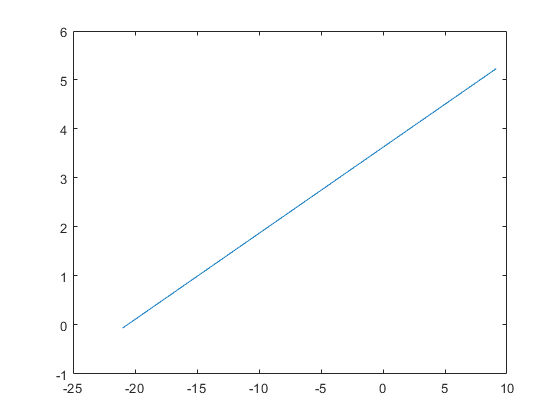


plot(alpha,CLPowered)


%Inboard Props
y1 = 19 %ft to centerline of prop

y1 = 19

z1 = x1*tand(ThrustAngle+PropUpwashAngle-PropDownwashAngle)+zProp %Assuming Prop is in line with MAC on wing

z1 = 4.4921

b1 = 2*sqrt(Rp^2-z1^2)

b1 = 17.8685

c1 = cr*(1-(1-TaperRatio)*2*y1/b)

c1 = 16.5361

S1 = b1*c1

S1 = 295.4743

AReff1 = b1/c1

AReff1 = 1.0806

dSlipstreamDynPressure1 = S*ThrustCoef/(pi*Rp^2)

dSlipstreamDynPressure1 = 2.2560

dCLWash1 = (1+dSlipstreamDynPressure1)*S1/S*LiftCurveSlope*dWingAoA*K1

dCLWash1 = -0.0257

dCLq1 = K1*dSlipstreamDynPressure1*S1/S*CLMaxFlapped

dCLq1 = 0.8297


%Outboard Props
y2 = 45.5 %ft to centerline of prop

y2 = 45.5000

z2 = x2*tand(ThrustAngle+PropUpwashAngle-PropDownwashAngle)+zProp %Assuming Prop is in line with MAC on wing

z2 = 5.0203

b2 = 2*sqrt(Rp^2-z2^2)

b2 = 17.2970

c2 = cr*(1-(1-TaperRatio)*2*y2/b)

c2 = 11.0125

S2 = b2*c2

S2 = 190.4829

AReff2 = b2/c2

AReff2 = 1.5707

dSlipstreamDynPressure2 = S*ThrustCoef/(pi*Rp^2)

dSlipstreamDynPressure2 = 2.2560

dCLWash2 = (1+dSlipstreamDynPressure2)*S2/S*LiftCurveSlope*dWingAoA*K1

dCLWash2 = -0.0166

dCLq2 = K2*dSlipstreamDynPressure2*S2/S*CLMaxFlapped

dCLq2 = 0.5349


ImmersedRatio = (2*S1+2*S2)/S

ImmersedRatio = 0.5741


CLMaxPowered = CLMaxFlapped + K*(4*dCLPropNorm + 2*dCLWash1 + 2*dCLq1 + 2*dCLWash2 + 2*dCLq2)

CLMaxPowered = 5.3011